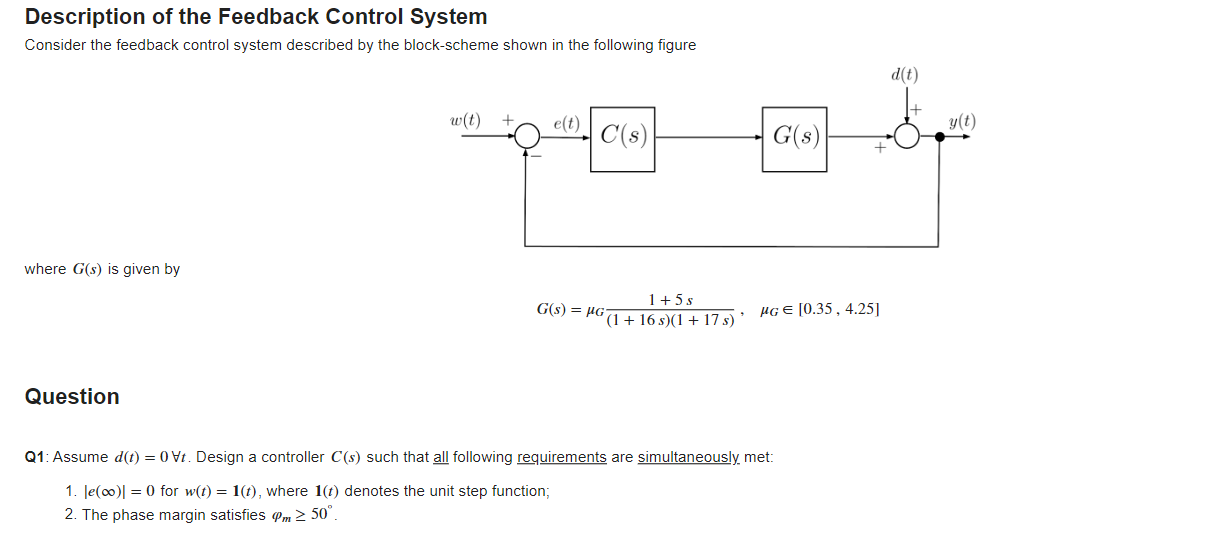

**PROGETTO STATICO**

Per soddisfare il primo requisito (Q1.1) è necessario che la FdT $L(s)$ sia di grado $g \ge 1$. Per semplicità scegliamo $g=1$, questo significa che dobbiamo aggiungere un integratore al controllore


$$C(s) = \frac{\mu_C}{s} \quad \Longrightarrow \quad L(s) = \mu_C\, \mu_G\, \frac{(1+5\,s)}{s\,(1+16\,s)(1+17\,s)}$$


A questo punto, prima di continuare con il progetto del controllore, studiamo i Diagrammi di Bodedi $L(j\omega)$

% let's define the transfer function builder element
s=tf('s');

pre_muC =1;  % preliminar gain for the controller
pre_muG = 1; % preliminar gain for the process

pre_C1s = pre_muC/(s);                        % the preliminary controller C(s)
pre_Gs = pre_muG*(1+5*s)/((1+16*s)*(1+17*s)); % the preliminary process G(s)

pre_Ls = pre_C1s*pre_Gs;                      % the preliminary open-loop transfer function L(s) C(s)
                                              % Note: there is no zero/pole
                                              % (or pole/zero)
                                              % simplification, so we don't
                                              % need to use the function
                                              % minreal( )


[ha1, ha2] = drawBodediagrams(pre_Ls);

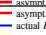

legend(ha1, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'best')
legend(ha2, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'best')
phaseM = +50; % the desired minimum phase margin
feas_Ls_Phase = -180+phaseM; % the minimum value of the arg L(j omega) 
                             % to guarantee the feasibility of the design

YLIMS = ylim(ha2);
OMLIMs = xlim(ha2);

% the (Q1.2) constraint
minOmega1 = OMLIMs(1);
maxOmega1 = OMLIMs(2);
PhLIM = feas_Ls_Phase;

Vert1 = [minOmega1 ,  YLIMS(1); minOmega1 ,PhLIM; ...
         maxOmega1 , PhLIM; maxOmega1 , YLIMS(1)];
Faces1 = [1  2  3  4];
hold on;
patch(ha2, 'Faces',Faces1,'Vertices',Vert1,...
        'FaceColor','yellow','FaceAlpha',.15, ...
        'EdgeColor', 'none'); % the pale yellow region is the forbidden one

**PROGETTO DINAMICO**

Prima di analizzare il secondo requisito, notiamo che i Diagrammi di Bode Di $L(j\omega)$:

- non sono influenzati per qualsiasi valore positivo di $\mu_g$

- non sono neppure influenzati dal valore di $\mu_c$

Per soddisfare il requisito (Q1.2), procediamo per cancellazione dinamica, ovvero introduciamo un controllore $C_2(s)$ tale che:


$$\left\{ \begin{array}{rcl}
C_1(s) &=& \frac{\mu_C}{s}\\
C_2(s) &=& \frac {(1+16s)(1+17s)}{(1+5s)} \\
C(s) &=& C_1(s) \cdot C_2(s) = \mu_C \, \frac{(1+16s)(1+17s)}{s(1+5s)}
\end{array} \right. \quad \Longrightarrow \quad 
L(s) = C(s) \cdot G(s) = \frac{\mu_C \mu_g}{s}
$$


Osserviamo che per qualsiasi valore di $\mu_c$ e $\mu_g$ abbiamo $\varphi_m = 90\degree $

Non ci resta che fissare il valore di $\mu_c$ e verificare i risultati ottenuti mediante il **Control System Designer App**

s = tf('s');

% Define the controller C(s)

Cs = ((1+16*s)*(1+17*s))/(s*(1+5*s))

Cs =
 
  272 s^2 + 33 s + 1
  ------------------
      5 s^2 + s
 
Continuous-time transfer function.
Model Properties



% Define the function G(s)

muG1 = 0.35; % the minimum gain
muG2 = 4.25; % the maximum gain
muG3 = 1; % an intermediate value

Gs1 = muG1*(1+5*s)/((1+16*s)*(1+17*s)); 
Gs2 = muG2*(1+5*s)/((1+16*s)*(1+17*s)); 
Gs3 = muG3*(1+5*s)/((1+16*s)*(1+17*s)); 

Gs = stack(1, Gs1, Gs2, Gs3);

controlSystemDesigner(Gs, Cs)